# CSP 이해하기 - 염홍기 교수님 BCI 8강

- 임의의 예제 데이터 생성

clear all; close all; clc; %초기화

%class 1 data
n = 100;
x1(:,1) = randn(n, 1);
x1(:,2) = x1(:,1) + randn(n, 1);
figure;
plot(x1(:,1), x1(:,2), 'b*')

%class 2 data
x2(:,1) = randn(n, 1);
x2(:,2) = 4*x2(:,1) + randn(n, 1); %기울기 변화
hold on;
plot(x2(:,1), x2(:,2), 'ro')

         2. eigenvector 구하기 (PCA)

%각 class의 eigenvector와 eigenvalue 구하기
[v1, d1] = eig(cov(x1));
[v2, d2] = eig(cov(x2));

%원점으로부터 위치벡터 표시 위하여
x1_v = [[0;0], v1(:,2)];
x2_v = [[0;0], v2(:,2)];  
line(x1_v(1,:), x1_v(2,:), 'LineWidth',2, 'Color',[0 0 1]); %rgb
line(x2_v(1,:), x2_v(2,:), 'LineWidth',2, 'Color',[1 0 0]);

        3. 데이터 분류하기 (CSP)

 하나의 데이터에 대해서는 분산이 최대, 다른 하나의 데이터에 대해서는 분산이 최소가 되는 벡터를 찾은 다음에 원래의 데이터에 곱해주면 분류가 잘 되는 데이터가 된다.

 이때의 벡터는 각각의 class에 대하여 covariance 행렬을 구하고, 두 covariance에 대한 eigen 벡터를 구하면 된다. (PCA)

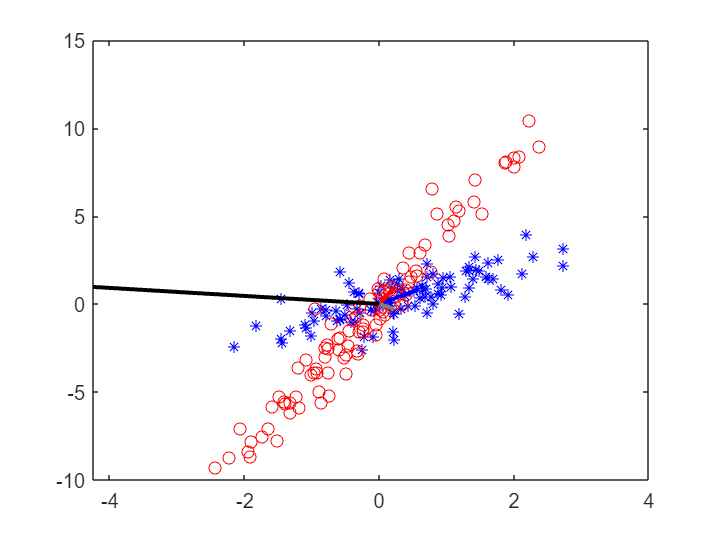

%CSP
[csp, csp_d] = eig(cov(x1), cov(x2)); %'x' 데이터는 반드시 [trial * features] 형태

csp_v = [[0;0], csp(:,2)];
line(csp_v(1,:), csp_v(2,:), 'LineWidth',2, 'Color',[0 0 0]);
csp_v1 = [[0;0], csp(:,1)];
line(csp_v1(1,:), csp_v1(2,:), 'LineWidth',2, 'Color',[0.5 0.5 0.5]);

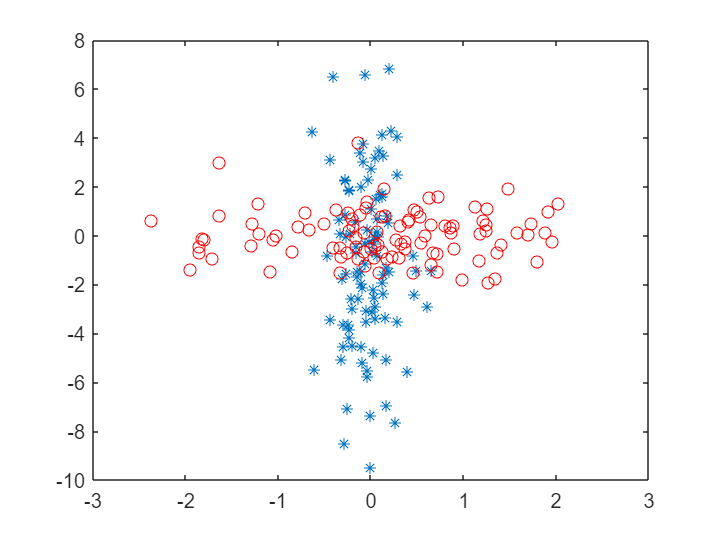


%데이터에 CSP 적용하기
csp_x1 = x1 * csp;
csp_x2 = x2 * csp;
figure;
plot(csp_x1(:,1), csp_x1(:,2), '*', csp_x2(:,1), csp_x2(:,2), 'ro');
hold on;

- iCSP

        : 어제 찍은 데이터와 오늘 찍은 데이터 사이의 차이. 노이즈를 최소화

        : 노이즈의 covariance 행렬 또한 사용

- CSSP

        : spectral이 추가되어, 뇌파 데이터에 일정값만큼 time delay 시킨 데이터를 함께 사용

        : band-pass 필터링 효과를 주어 spectral한 특징까지 같이 고려할 수 있음

- FBCSP

        : 뇌파 데이터가 있을 때 각각 여러 주파수로 band-pass 필터링을 하는 것